**Problem 4: Linear Regression and it's regression**

Preparing train and test sets for models

data = load('housing.data');
x = data(:, 1:13);
y = data(:, 14);
[n, d] = size(x);

seed = 2; rand('state', seed); randn('state', seed);
perm = randperm(n);  % remove any possible ordering fx
x = x(perm, :); y = y(perm);
Ntrain = 300;
Xtrain = x(1:Ntrain, :); ytrain = y(1:Ntrain);
Xtest = x(Ntrain + 1:end, :); ytest = y(Ntrain + 1:end);

**Part 2**

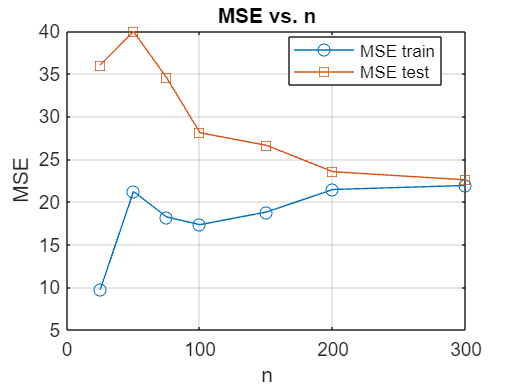

n = [25 50 75 100 150 200 300];

MSE_train = zeros(size(n));
MSE_test = zeros(size(n));

for i = 1:length(n)
    % Normalizing the train data
    [st_array1, m1 , s1] = zscore(Xtrain(1:n(i), :));
    X_train = [ones(size(Xtrain(1:n(i), :), 1), 1) st_array1];
    % Normalizing the test data
    s_test = (Xtest-m1)./s1;
    X_test = [ones(size(Xtest, 1), 1) s_test];
    y_train = ytrain(1:n(i));
    weights = pinv(X_train'*X_train)*(X_train' * y_train);
    MSE_train(i) = ((X_train * weights - y_train)' * (X_train * weights - y_train))/n(i);
    MSE_test(i) = ((X_test * weights - ytest)'*(X_test * weights - ytest))/size(X_test, 1);
end

% Create a plot
figure;
plot(n, MSE_train, '-o', 'DisplayName', 'MSE train');
hold on;
plot(n, MSE_test, '-s', 'DisplayName', 'MSE test');
xlabel('n');
ylabel('MSE');
title('MSE vs. n');
legend('Location', 'Best');
grid on;
hold off;

Expanding the size of the training dataset equips the model with a richer source of information, typically resulting in superior adaptability to unseen data, consequently reducing test error.

In scenarios where the training dataset is limited in size, the model can excessively tailor its predictions to the confined data, occasionally veering into overfitting. With the enlargement of the training dataset, the information to be absorbed becomes more multifaceted and intricate to accommodate flawlessly, leading to an upturn in training error.

Furthermore, as the training dataset's dimensions augment and edge nearer to the complete dataset, the model undergoes exposure to a more comprehensive portion of the available data during training. As a result, its performance on both the training set and the test set starts to draw closer, culminating in the convergence of the two error curves.

**Part 3**

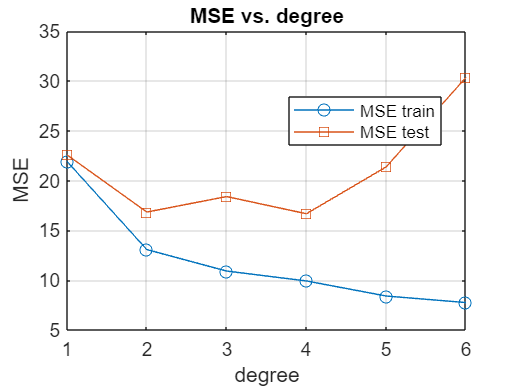

deg = [1 2 3 4 5 6];

MSE_train = zeros(size(deg));
MSE_test = zeros(size(deg));

for i = 1:length(deg)
    % Train Feature expansion
    X_train = degexpand(Xtrain, deg(i), 1);
    [X_train(:, 2:end), mean, std] = zscore(X_train(:, 2:end));
    y_train = ytrain;
    y_test = ytest;
    % Test feature expansion
    X_test = degexpand(Xtest, deg(i), 1);
    X_test(:, 2:end) = (X_test(:, 2:end)-mean)./std;
    weights = pinv(X_train'*X_train) * X_train' * y_train;
    MSE_train(i) = ((X_train * weights - y_train)' * (X_train * weights - y_train))/size(X_train, 1);
    MSE_test(i) = ((X_test * weights - y_test)'*(X_test * weights - y_test))/size(X_test, 1);
end

% Create a plot
figure;
plot(deg, MSE_train, '-o', 'DisplayName', 'MSE train');
hold on;
plot(deg, MSE_test, '-s', 'DisplayName', 'MSE test');
xlabel('degree');
ylabel('MSE');
title('MSE vs. degree');
legend('Location', 'Best');
grid on;
hold off;

As the polynomial degree is raised, the model gains greater adaptability, allowing it to conform more closely to the training data, subsequently decreasing the training error.

In the early stages, the increased adaptability of the model aids in capturing the fundamental data patterns, which, in turn, results in a decrease in the test error. However, there comes a point where the model begins to overfit. In essence, it starts fitting the training data with excessive precision, encompassing not only the genuine patterns but also the noise and outliers. This diminishes its capacity to generalize effectively to new data, ultimately leading to an uptick in test error.

**Part 4**

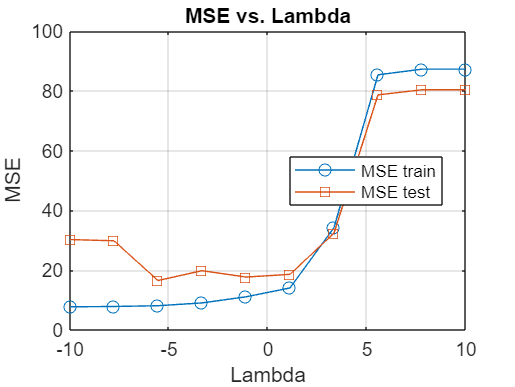

lambdas = [0 logspace(-10, 10, 10)];

X_train = degexpand(Xtrain, 6, 1);
[X_train(:, 2:end), mean, std] = zscore(X_train(:, 2:end));
y_train = ytrain;
y_test = ytest;
X_test = degexpand(Xtest, 6, 1);
X_test(:, 2:end) = (X_test(:, 2:end)-mean)./std;
I = eye(size(X_train, 2));
% To avoid regularizing the bias term, put I(0,0) = 0
I = [zeros(size(I, 1), 1), I(:,2:end)];

MSE_train = zeros(size(lambdas));
MSE_test = zeros(size(lambdas));

for i = 1:length(lambdas)
    weights = pinv(X_train'*X_train + lambdas(i)* I) * X_train' * y_train;
    MSE_train(i) = (((X_train * weights - y_train)' * (X_train * weights - y_train)))/size(X_train, 1);
    MSE_test(i) = ((((X_test * weights - ytest)'*(X_test * weights - ytest))))/size(X_test, 1);
end

% Create a plot
figure;
plot(log10(lambdas), MSE_train, '-o', 'DisplayName', 'MSE train');
hold on;
plot(log10(lambdas), MSE_test, '-s', 'DisplayName', 'MSE test');
xlabel('Lambda');
ylabel('MSE');
title('MSE vs. Lambda');
legend('Location', 'Best');
grid on;
hold off;

Initially, regularization helps in avoiding overfitting. But as seen from the plot, as the regularization increases, the model starts to underfit which leads to an increased mean squared error.

**Part 5**

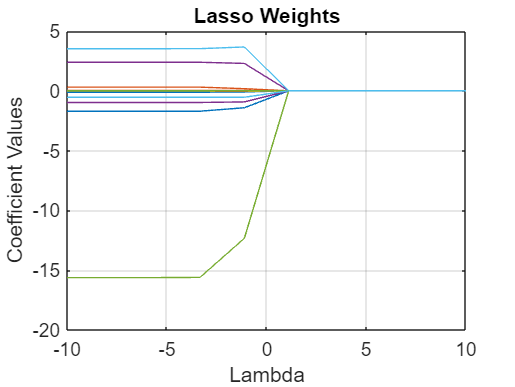

lambdas = logspace(-10, 10, 10);

[weights, FitInfo] = lasso(Xtrain, ytrain, 'Lambda', lambdas);

figure;
plot(log10(lambdas), weights);
xlabel('Lambda');
ylabel('Coefficient Values');
title('Lasso Weights');
grid on;

We observe that as the regularization increases, the weights are pushed towards zero.